clear;      % Remove todas as variáveis
load('dados_ini_aero.mat')

PROJETO 2025 

PERFIL ASA FX74CL_140_ 35% de inteporlação

PERFIL EMPENAGEM HORIZONTAL AH 79-100c

PERFIL EMPENAGEM VERTICAL 

##                                            Contribuição da Asa

Em geral para aeronaves convencionais a Asa deve contribuir de maneira desestabilizante, ou seja a sua derivada deve ser negativa. Exceto em casos como uma asa voadora.

cl0w = 0.626438


Cm0w = -0.267468


Cmlphaw = 0.000737


Clalphaw = 0.073681


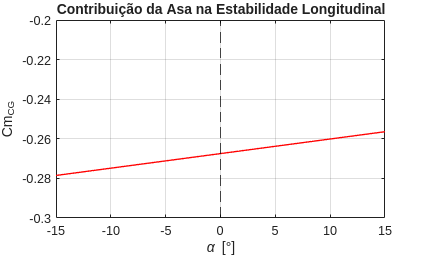

##                          Contribuiçao do Estabilizador Horizontal

%% Contribuição do Estabilizador Horizontal
fprintf("CONTRIBUIÇÃO DO ESTABILIZADOR HORIZONTAL PARA ESTABILIDADE LONGITUDINAL\n");

CONTRIBUIÇÃO DO ESTABILIZADOR HORIZONTAL PARA ESTABILIDADE LONGITUDINAL



% 1. Inputs
clalphah = 0.0886;%do perfil
etah = 0.9;         % Eficiência da cauda
cl0=0.904;           %em relação ao perfil
cl0h=-cl0/clalphah;  %em relação ao perfil


% 2. Variáveis de Design
bh = 0.8; % Envergadura do estabilizador horizontal [m]
ch = 0.25

ch = 0.2500

lh= 0.8

lh = 0.8000

%Vh = 0.4; % Volume de cauda
%ARh = 1.8; % Alongamento do estabilizador horizontal
alpha0h = 0; % Ângulo de ataque de inclinação do est abilizador horizontal [graus]
alpha0w =1; % Ângulo de ataque de inclinação da asa [graus]

% 3. Cálculos
[Clalphah, epsilon_dalpha, Cm0h, epsilon0d, Sh, Cmalphah,CL0h,eh, Vh, ch, ARh] = ...
    Contr_Est_Hor(Sw, cw, clalphah, bh, ch, lh , etah, alpha0w , alpha0h, Clalphaw, ARw, cl0w,cl0,cl0h) 

Sh = 0.2000

ARh = 3.2000

Vh = 0.3963

Clalphah = 0.0549

epsilon_dalpha = 0.4962

Cm0h = 0.3018

epsilon0d = 4.2188

Sh = 0.2000

Cmalphah = -0.0099

CL0h = 0.5598

eh = 0.8212

Vh = 0.3963

ch = 0.2500

ARh = 3.2000

bht=ch*ARh

bht = 0.8000

% 4. Variáveis Geométricas
fprintf('            Requisitos para Garantir que a contribuição do EH é estabilizante');

            Requisitos para Garantir que a contribuição do EH é estabilizante

fprintf(' ');

disp(table(Cm0h,Cmalphah, 'VariableNames', {'Coeficiente de momento nulo do EH', 'Coeficiente de momento X alpha'}))

    Coeficiente de momento nulo do EH    Coeficiente de momento X alpha
    _________________________________    ______________________________

                 0.30181                           -0.0098592          



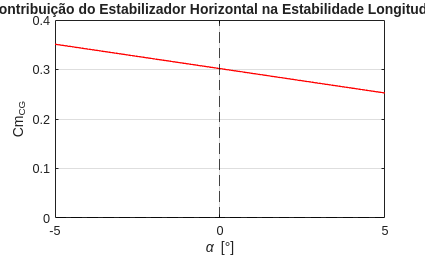


% 5. Plotagem
alpha_deg = linspace(-5, 5, 100); % Ângulo de ataque de -5 a 5 graus
Cmh = Cm0h + Cmalphah * alpha_deg;
figure;
plot(alpha_deg, Cmh, 'r-', 'LineWidth', 1);
grid on;
title('Contribuição do Estabilizador Horizontal na Estabilidade Longitudinal');
xlabel('\alpha [°]');
ylabel('Cm_{CG}');
xline(0, '--k');
yline(0, '--k');

##                      Curva CmCG X Alpha da aeronave completa

Para a Análise da Aeronave completa, devemos seguir os critérios para atingir a estabilidade Longitudinal Estática. Tentar não  trabalhar com Volume de cauda muito elevado, manter também o quociente entre a distancia do CA da asa até o CG da Empenagem aproximado de 2, o Angulo de trimagem deve seguir a seguinte restrição de 0 < Angulo de trimagem << Angulo de estol da Asa, a margem estática entre 5% e 20%, lembrando que quando mais proxima de 0 menos estavel e mais controlavel, e quando mais distante, menos controlavel e mais estável, o Projetista em questão deve avaliar o ponto neutro e garantir o critério de que Hpn>Hcg. Seguindo esses parâmetros conseguimos então dizer que a aeronave é estáticamente estável!

fprintf('\n==================================================================================================================');

fprintf('  ')

%% Análise da Aeronave Completa
fprintf("                                          CARACTERISTICAS DA EMPENAGEM\n");

                                          CARACTERISTICAS DA EMPENAGEM



% 1. Cálculos
[ME, Cmalpha, Cm0, hPN, alpha_trim, lhcw] = Est_Aeronave(Cmalphaw, Cmalphah, Clalphaw, hCG, hacw, Cm0w, Cm0h, Vh, etah, epsilon_dalpha, Clalphah, lh, cw);
% 2. Variáveis Importantes
disp(table(Sh, Vh, bh, lh, 'VariableNames',{'Área do EH (m²)', 'Volume da de cauda EH', 'Envergadura do EH', 'braço do CA até o o CA do EH'}))

    Área do EH (m²)    Volume da de cauda EH    Envergadura do EH    braço do CA até o o CA do EH
    _______________    _____________________    _________________    ____________________________

          0.2                 0.39634                  0.8                       0.8             



fprintf('  ')

fprintf('\n==================================================================================================================\n\n                                   ANÁLISE DE ESTABILIDADE LONGITUDINAL ESTÁTICA');



                                   ANÁLISE DE ESTABILIDADE LONGITUDINAL ESTÁTICA

fprintf('  ')

fprintf('  ')

disp(table(alpha_trim,ME, lhcw, hPN, Cm0, 'variableNames',{'Angulo de trimagem (Graus)', 'Margem Estática', 'Quociente de cw e lh' 'Ponto Neutro', 'Cm0'}))

    Angulo de trimagem (Graus)    Margem Estática    Quociente de cw e lh    Ponto Neutro      Cm0   
    __________________________    _______________    ____________________    ____________    ________

              3.7642                  0.12381               1.8522             0.38381       0.034338



fprintf('  ')

fprintf('\n==================================================================================================================');

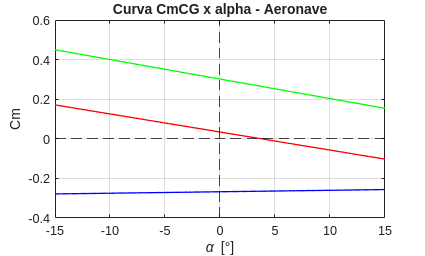

% 3. Plotagem
alpha_deg = linspace(-15, 15, 100); % Ângulo de ataque de -15 a 15 graus
CmCG = Cm0 + Cmalpha * alpha_deg;
Cmw = Cm0w + Cmalphaw * alpha_deg;
Cmh = Cm0h + Cmalphah * alpha_deg;
figure;
plot(alpha_deg, CmCG, 'r-', 'LineWidth', 1);
hold on
plot(alpha_deg, Cmw, 'b-', 'LineWidth', 1);
plot(alpha_deg, Cmh, 'g-', 'LineWidth', 1);
grid on;
title('Curva CmCG x alpha - Aeronave');
xlabel('\alpha [°]');
ylabel('Cm_{}');
xline(0, '--k');
yline(0, '--k');

**ESTABILIDADE DIRECIONAL**

Contribuição da Asa-fuselagem p/ Estabilidade Lateral
Contribuição da Empenagem Vertical p\ Estabilidade Lateral
Contribuição da Aeronave completa c/ relação a Estabilidade Lateral
Funções
Parâmetros da Nova Empenagem para Estimativa
LIMITACAO 2025

## Contribuição da Asa-fuselagem p/ Estabilidade Lateral

A contribuição da asa é bem inferior se você considerar a asa como referência, entretanto a Fuselagem e outras estruturas como trem de pouso e Nacelles, em um caso geral, possuem efeito **DESESTABILIZANTE **para estabilidade direcional. Essa contribuição é calculada com o uso de dados Semi-Empíricos, ou seja, obter dados apartir de dados experimentais anteriores.

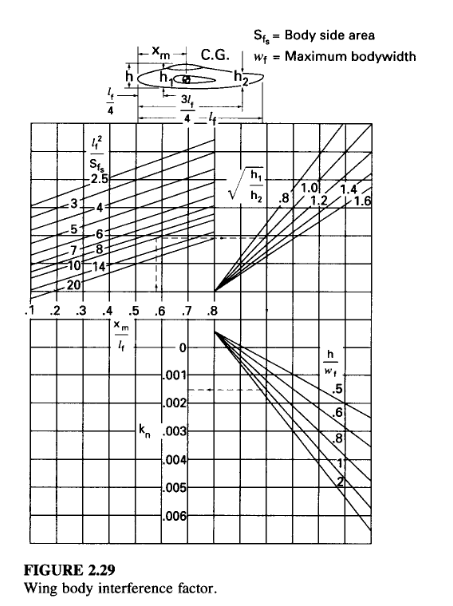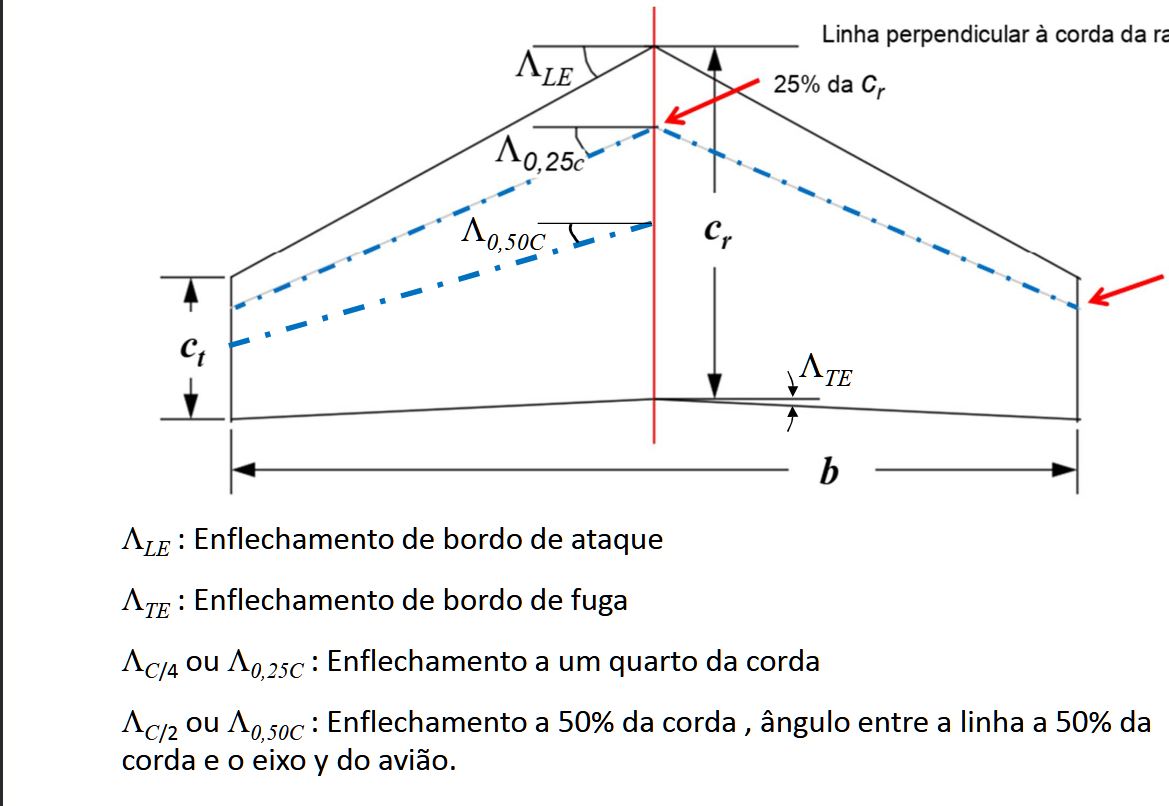

Embora já estejam bem definida a sua variação média no código, é bom ressalta-las mais uma vez. São dados empíricos:

- $K_n$ Fator de interferencia Asa-Fuselagem 


$$0,001\le K_n \le 0,005$$


- $K_{\textrm{Rl}}$ Fator de correção para o número de reynolds


$$K_{\textrm{Rl}} =1$$


%inputs fuselagem
Kn= 0.0025; %Fator Empirico - há relação com a geometria da fuselagem. Varia entre  0,001 < Kn < 0,005
kRL=1; %Variavel Empirica relacionada com o Numero de Reynolds da Fuselagem. 1 <= kRL <= 2,2
Sf=0.0357; %Area da fuselagem do plano Lateral
lF= 0.550; %comprimento da fuselagem
dF=0.093; % profundidade da fuselagem
CosA=1; %É o cosseno do ângulo de enflechamento da asa medido à 25% da corda da asa 
Zw=0.06; %altura projetada no eixo vertical da aeronave, entre o CG e o CA da Asa ( Linha da corda)
[cnbetawf]= contr_asafuse_vert(Kn, kRL, Sf, lF, Sw, bw);
fprintf('cnbetawf = %.10f\n', cnbetawf);

cnbetawf = -0.0000233427


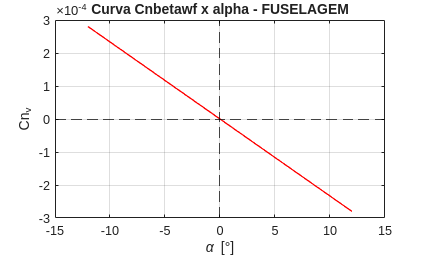

% 3. Plotagem
alpha_deg = linspace(-12, 12, 100); % Ângulo de ataque de -12 a 12 graus
Cmv = cnbetawf* alpha_deg;
figure;
plot(alpha_deg, Cmv, 'r-', 'LineWidth', 1);
grid on;
title('Curva Cnbetawf x alpha - FUSELAGEM');
xlabel('\alpha [°]');
ylabel('Cn_{v}');
xline(0, '--k');
yline(0, '--k');

## Contribuição da Empenagem Vertical p\ Estabilidade Lateral

Coeficiente Angular da curva do coeficeinte de sustentação em função do ângulo de ataque para o Estabilizador Vertical. Como já temos a Empenagem horizontal, ocorre um efeito de interferencia no Estabilizador vertical que toran essa superficie mais **EFICIENTE. **Vale ressaltar que, a partir de PHILLIPS sabemos que a empenagem vertical e a fuselagem tem um grande efeito na razãoo de aspecto aparente do Estabilizador Vertical, pois elas são como Winglets para o Estabilizador Vertical, aumento sua sustentação para um angulo de ataque. Os cálculos são trabalhosos, ja que que resolvi trabalhar com GUDMUSSON, PHILLIPS e ROSKAM a apartir da Teoria da linha de Prandtl.

%inputs empenagem vertical
clalphav = 0.07596363636; % coeficiente angular do perfil
Sv=0.036; %área da EV
lv=0.55; %Distancia do CG da aeronave ao CA da EV
ARv= 1; %razao de aspecto do ev
lambdav = 0.5;% afilamento
% 2. Parâmetros de Design
[Sv,crv,cpv, offset_tip,tan_LE, tang_c_2_v, bv, Clalphav,ARveff]=Geometria(Sv,ARv,lambdav, clalphav, Sh, ARh);
[Vv, Cnbetav, etah_v]=Contr_Est_Vert(Sv,lv, Sw, bw, ARw, Zw, dF, CosA, Clalphav, clalphav);

Vv = 0.0094

%Geometria
fprintf('clalphav = %f\n',clalphav)

clalphav = 0.075964


fprintf('Clalphav Metódo do Roskam e Philips= %f\n',Clalphav)

Clalphav Metódo do Roskam e Philips= 0.037982


fprintf('cnbetav = %f\n', Cnbetav);

cnbetav = 0.000779


fprintf('Sv = %.4f m^2\n', Sv);

Sv = 0.0360 m^2


fprintf('Razão de Aspecto do EV (ARv) = %f\n',ARv)

Razão de Aspecto do EV (ARv) = 1.000000


fprintf('Razão de Aspecto Efetiva(ARv) = %f\n',ARveff)

Razão de Aspecto Efetiva(ARv) = 11.057988


fprintf('Angulo de inclinação da reta do trapézio (Tan_LE) = %f\n',tan_LE)

Angulo de inclinação da reta do trapézio (Tan_LE) = 0.666667


fprintf('Angulo de inclinação da reta do trapézio da 2º seção (tang_c_2_v) = %f\n',tang_c_2_v)

Angulo de inclinação da reta do trapézio da 2º seção (tang_c_2_v) = 0.000000


fprintf('Afilamento do Ev (lambdav) = %f\n',lambdav)

Afilamento do Ev (lambdav) = 0.500000


fprintf('crv = %.4f m\n', crv);

crv = 0.2530 m


fprintf('cpv = %.4f m\n', cpv);

cpv = 0.1265 m


fprintf('bv = %.4f m\n', bv);

bv = 0.1897 m


[ev, Clalphav]=Nelson_method(ARv,clalphav);
fprintf('clalphav = %f\n',clalphav)

clalphav = 0.075964


fprintf('Clalphav Metódo do NELSON= %f\n',Clalphav)

Clalphav Metódo do NELSON= 0.024714


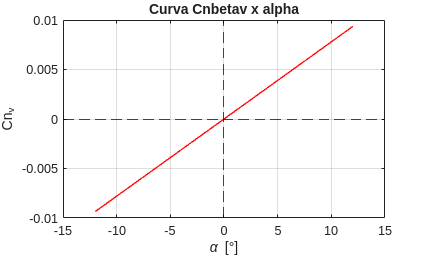

% 3. Plotagem
alpha_deg = linspace(-12, 12, 100); % Ângulo de ataque de -12 a 12 graus
Cmv = Cnbetav* alpha_deg;
figure;
plot(alpha_deg, Cmv, 'r-', 'LineWidth', 1);
grid on;
title('Curva Cnbetav x alpha');
xlabel('\alpha [°]');
ylabel('Cn_{v}');
xline(0, '--k');
yline(0, '--k');

## Contribuição da Aeronave completa c/ relação a Estabilidade Lateral

por roskam Cnbeta tem um nivel geral de 0.0010 1/deg

[cnbeta]=estab_dir_comp(Cnbetav, cnbetawf);

% 3. Plotagem
alpha_deg = linspace(-12, 12, 100); % Ângulo de ataque de -12 a 12 graus
cmv1 = cnbetawf* alpha_deg;
cmv2 = Cnbetav * alpha_deg;
cmv3 = cnbeta*alpha_deg;
fprintf('cnbeta = %f\n', cnbeta);

cnbeta = 0.000756


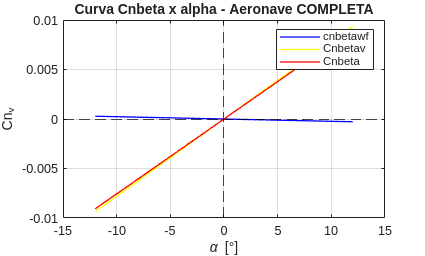

figure;
plot(alpha_deg, cmv1, 'b-', 'LineWidth', 1); % Primeira curva
hold on; % Mantém o gráfico para adicionar mais curvas
plot(alpha_deg, cmv2, 'y-', 'LineWidth', 1); % Segunda curva
plot(alpha_deg, cmv3, 'r-', 'LineWidth', 1); % Terceira curva

% Personalização do gráfico
grid on;
title('Curva Cnbeta x alpha - Aeronave COMPLETA');
xlabel('\alpha [°]');
ylabel('Cn_{v}');
xline(0, '--k'); % Linha vertical no zero
yline(0, '--k'); % Linha horizontal no zero
legend('cnbetawf', 'Cnbetav', 'Cnbeta'); % Legenda para diferenciar as curvas
hold off; % Finaliza a sobreposição de gráficos				


disp(table(Sv, Vv, bv, lv, 'VariableNames',{'Área do EV (m²)', 'Volume da de cauda EV', 'Envergadura do EV', 'braço do CA até o o CA do EV'}))

    Área do EV (m²)    Volume da de cauda EV    Envergadura do EV    braço do CA até o o CA do EV
    _______________    _____________________    _________________    ____________________________

         0.036               0.0094155               0.18974                     0.55            



fprintf('  ')

fprintf('\n==================================================================================================================\n\n                                   ANÁLISE DE ESTABILIDADE VERTICAL ESTÁTICA');



                                   ANÁLISE DE ESTABILIDADE VERTICAL ESTÁTICA

fprintf('  ')

fprintf('  ')

Cy_beta_v = -Clalphav * etah_v * (Sv / Sw);
K_f = 0.8;
Cy_beta_fus = -K_f * (Sf / Sw);
Cy_beta = Cy_beta_v + Cy_beta_fus

Cy_beta = -0.0316

## ESTABILIDADE LATERAL

 apresenta um método semi-empírico simplificado onde utiliza-se dois fatores de correção para o diedro. 

A partir da figura 5.6.3 de [PHILLIPS] pode-se considerar que:

0,85≤κΓ≤0,87

Zv=0.3;
k=0.86;

%Contribuição da asa (diedro efetivo por posição)
Cl_beta_zw = -(1.2*sqrt(ARw))*(Zw/bw)*((2*dF)/bw);
fprintf('Cl_beta_zw = %.6f\n', Cl_beta_zw);

Cl_beta_zw = -0.006157



%Contribuição da empenagem vertical (efeito de estabilidade lateral)
Cl_beta_v = -(k*clalphav*etah_v*(Sv/Sw)*((Zv-lv)/bw)); %%% PRESTAR ATENÇAO NO CLAPHAV
fprintf('Cl_beta_v = %.6f\n', Cl_beta_v);

Cl_beta_v = 0.000305


clbeta= Cl_beta_zw + Cl_beta_v

clbeta = -0.0059

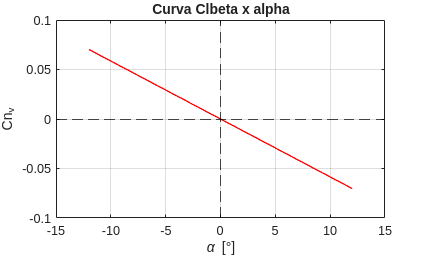

Clb= clbeta* alpha_deg;
figure;
plot(alpha_deg, Clb, 'r-', 'LineWidth', 1);
grid on;
title('Curva Clbeta x alpha');
xlabel('\alpha [°]');
ylabel('Cn_{v}');
xline(0, '--k');
yline(0, '--k');

Antes de qualquer coisa esse codigo ainda nao esta generealizado para o qualquer projeto, apenas serve para a asa a seguir,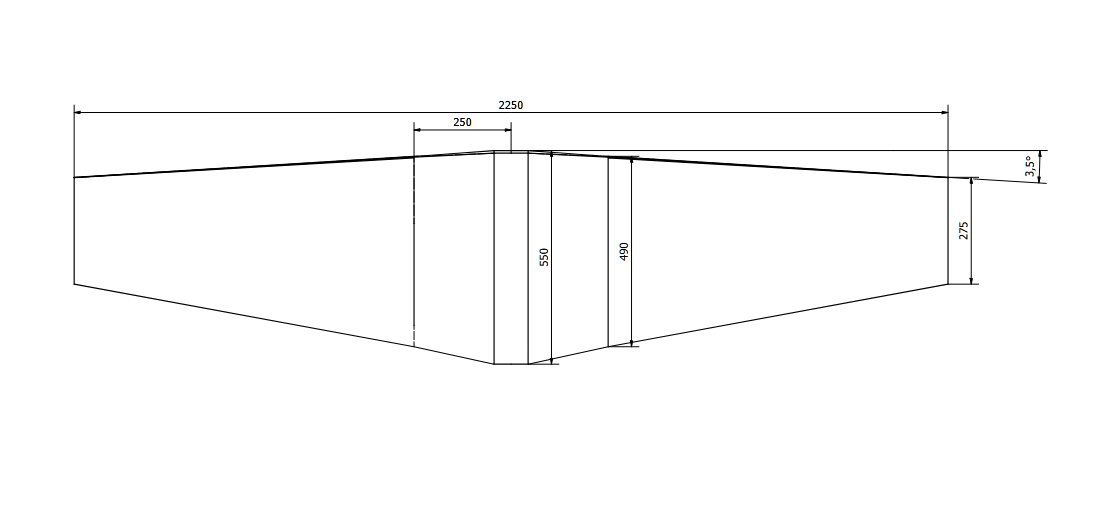

Foram feitos os calculos na mão afim de otimizar o tempo, ficando dessa forma:

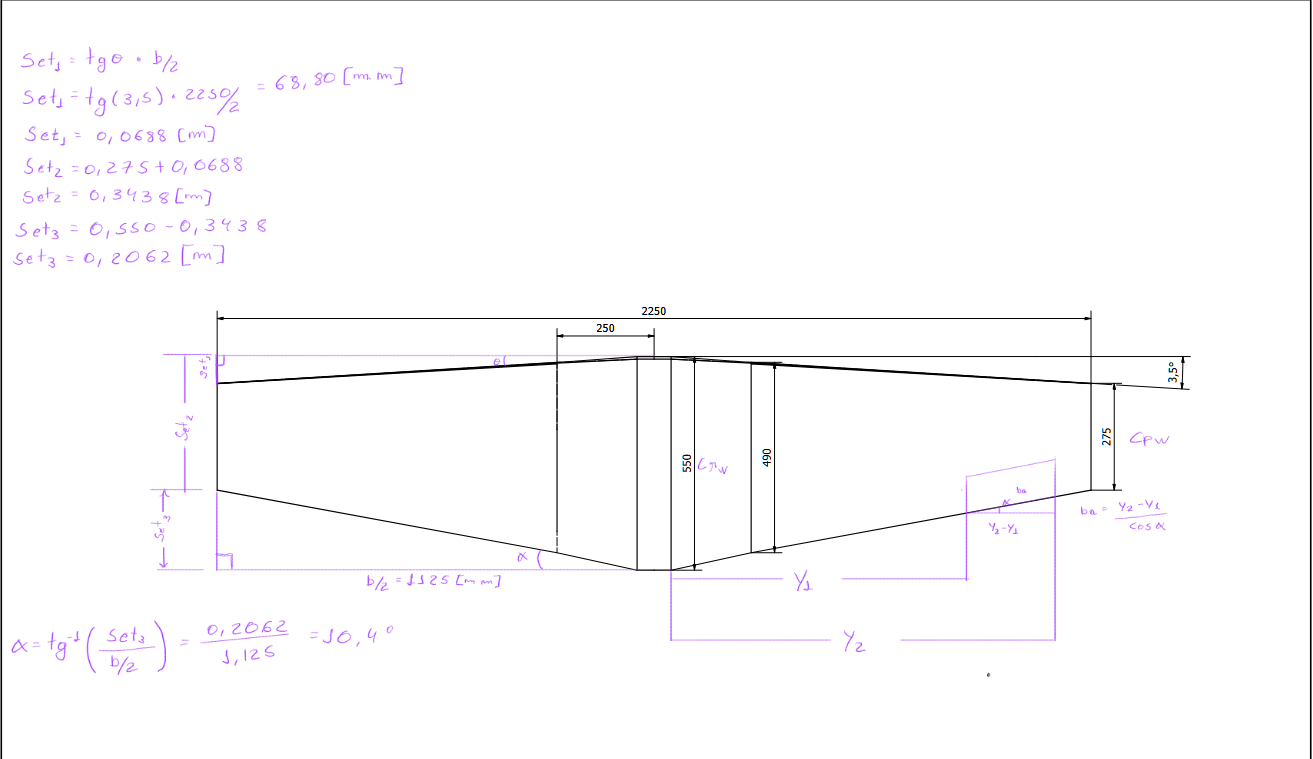

%% Geometria
b_2 = bw/2;
y1=0.60;  %distancia inicial aileron
y2=1.0; %distancia final aileron
croot=0.550;
cpoint=0.275;
chord_a=0.1; %corda do aileron
alphaA = 10.4; %angulo de enflechamento inferior da asa
ARa = ARw;% Razao de aspecto do aileron que é igual da asa
ba=(y2-y1); % eetah_vergadura do aileron
set4=(ba/(cosd(alphaA))); %hipotenusa do aileron
Sa=set4*chord_a; % Area do aileron
lambdaA=croot/cpoint;

fprintf('Sa = %f\n', Sa);

Sa = 0.040668


fprintf('corda aileron = %f\n', chord_a);

corda aileron = 0.100000



fprintf('ba = %f\n', ba);

ba = 0.400000


fprintf('Sa total = %f\n', Sa*2);

Sa total = 0.081336


fprintf('ba total = %f\n', ba*2);

ba total = 0.800000


fprintf('Corda na ponta = %f\n', cpoint);

Corda na ponta = 0.275000


fprintf('corda na raiz= %f\n', croot);

corda na raiz= 0.550000


fprintf('afilamento = %f\n', lambdaA);

afilamento = 2.000000



Sa_Sw= Sa/Sw; %quociente da area do aileron e da asa
ba_bw= ba/bw; %%quociente da eetah_vergadura do aileron e da asa
ca_cw= chord_a/cw;
y1_bw=y1/bw;
Cy_beta_v = -clalphav * etah_v * (Sv / Sw);



Aux1=(((2*Clalphaw*0.2)/Sw*bw));
syms y
func=croot*(1+((lambdaA-1)/(bw/2))*y)*y;
Aux2 = int(func, y, y1,y2);
fprintf('resultado da integral = %f\n', Aux2);

resultado da integral = 0.303763


CldetaA= Aux1* Aux2;

fprintf('CldeltaA = %f\n', CldetaA);

CldeltaA = 0.021552


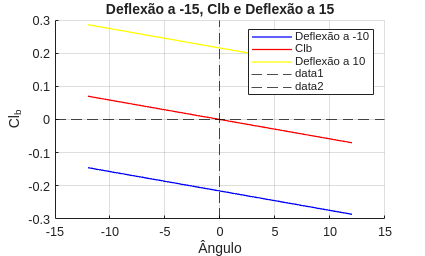


% -------- Deflexões --------
Clb_n10 = Clb + CldetaA * (-10); % Deflexão a -10 graus
Clb_0   = Clb;                   % Só estabilidade
Clb_p10 = Clb + CldetaA * ( 10); % Deflexão a +10 graus
figure;
hold on;
plot(alpha_deg, Clb_n10, 'b-',  'LineWidth', 1); % azul
plot(alpha_deg, Clb_0,   'r-',  'LineWidth', 1); % vermelho
plot(alpha_deg, Clb_p10, 'y',  'LineWidth', 1); % amarelo
grid on;
xlabel('Ângulo');
ylabel('Cl_b');
title('Deflexão a -15, Clb e Deflexão a 15');
legend('Deflexão a -10', 'Clb', 'Deflexão a 10');
xline(0, '--k');
yline(0, '--k');
hold off;

Clalpha=Clalphaw+Clalphav+Clalphah

Clalpha = 0.1533

save('final.mat')                        

##    Funções


% Função da Asa
function [Cmalphaw, lw, Cm0w] = Contr_Asa(hCG, hacw, cmac, cw, Clalphaw, cl0w) 
    lw = (hCG - hacw) * cw;
    Cm0w = cmac + (cl0w * (hCG - hacw));
    Cmalphaw = (lw / cw) * Clalphaw;
end

% Função do Estabilizador Horizontal
function [Clalphah, epsilon_dalpha, Cm0h, epsilon0d, Sh, Cmalphah,CL0h,eh, Vh, ch, ARh] = ...
    Contr_Est_Hor(Sw, cw, clalphah, bh, ch, lh, etah, alpha0w , alpha0h, Clalphaw, ARw, cl0w,cl0,cl0h) 
    % ch= Sh/bh; 
    %Sh = (bh^2) / ARh;
    Sh= ch*bh
    ARh = bh^2/Sh
    Vh= (Sh*lh)/(cw*Sw)
    % lh = (Vh * Sw * cw) / Sh;
    eh = 1 / (1 + 1 / (pi * ARh * (1.78 * (1 - 0.045 * exp(0.68) * log(ARh) - 0.64))));
    epsilon_dalpha = (57.3 *2* Clalphaw) / (pi * ARw); % Gradiente de downwaSh
    epsilon0d = (57.3 * 2 * cl0w) / (pi * ARw); % Ângulo de downwaSh para alpha = 0

    
    
  Clalphah = clalphah / (1 + (57.3 * clalphah / (pi * ARh * eh)));
    CL0h=-cl0h*Clalphah;
    Cm0h = (Vh * etah * Clalphah) * (alpha0w - alpha0h + epsilon0d) + (Vh * etah * CL0h);
    Cmalphah = -Vh * etah * Clalphah * (1 - epsilon_dalpha);
end

% Função da Aeronave Completa
function [ME, Cmalpha, Cm0, hPN, alpha_trim, lhcw] = Est_Aeronave(Cmalphaw, Cmalphah, Clalphaw, hCG, hacw, Cm0w, Cm0h, Vh, etah, epsilon_dalpha, Clalphah, lh, cw)
    Cmalpha = Cmalphaw + Cmalphah;
    Cm0 = Cm0h + Cm0w;
    alpha_trim = -Cm0 / Cmalpha; % Ângulo de trim em graus
    hPN = hacw + ((Vh * etah * Clalphah)/Clalphaw) * ((1 - epsilon_dalpha));
    ME = hPN - hCG;
    lhcw= lh/cw;
end
%função da Asa e fuselagem p/ estabilidade vetical
function [cnbetawf]= contr_asafuse_vert(Kn, kRL, Sf, lF, Sw, bw)
      cnbetawf = (-Kn*kRL*Sf*lF)/(Sw*bw);
end
%Função do estabilizador vertical		

%Geometria
function [Sv,crv,cpv, offset_tip,tan_LE, tang_c_2_v, bv, Clalphav, ARveff]=Geometria(Sv,ARv,lambdav, clalphav, Sh, ARh)

bv=sqrt(Sv*ARv); %envergadura
crv = Sv/((lambdav+1)*(bv/2)); %corda na ra iz
cpv = lambdav*crv; %corda na ponta
offset_tip = crv-cpv; % offset maximo
tan_LE = offset_tip/bv; % Angulo de inclinação da reta do trapézio
tang_c_2_v = tan_LE - (2/ARv)*((1-lambdav)/(1+lambdav));
% 3.2. Coeficiente Angular
% Figura 7.7. Roskan: Methods for Estimating Stability and Control Derivatives
kH = 0.176*((Sh/Sv)^3) - 0.8868*((Sh/Sv)^2) + 1.6361*(Sh/Sv) + 0.0018;

% 3.2.1. Razão de Aspecto Efetiva - [PHILLIPS: fig - 5.4.2]
if ARv <= 1.75
    ARveff_ARv = 0.0028*(ARh^5)-0.0372*(ARh^4)+0.1948*(ARh^3)-0.5196*(ARh^2)+0.7556*ARh+1.006;
elseif ARv > 1.75 && ARv <= 2
    ARveff_ARv = 0.0021*(ARh^5)-0.0287*(ARh^4)+0.1523*(ARh^3)-0.4131*(ARh^2)+0.6238*ARh+1.0044;
elseif ARv > 2 && ARv <= 2.25
    ARveff_ARv = 0.0018*(ARh^5)-0.0237*(ARh^4)+0.1259*(ARh^3)-0.343*(ARh^2)+0.5322*ARh+1.0055;
elseif ARv > 2.25 && ARv <= 3
    ARveff_ARv = 0.0015*(ARh^5)-0.0199*(ARh^4)+0.1072*(ARh^3)-0.2977*(ARh^2)+0.4744*ARh+1.0046;
elseif ARv > 3 && ARv <= 3.25
    ARveff_ARv = 0.0027*(ARh^5)-0.0313*(ARh^4)+0.1395*(ARh^3)-0.3198*(ARh^2)+0.4474*ARh+1.0068;
elseif ARv > 3.25 && ARv <= 4
    ARveff_ARv = 0.0024*(ARh^5)-0.0272*(ARh^4)+0.1229*(ARh^3)-0.2883*(ARh^2)+0.4123*ARh+1.0077;
end

ARveff = ARveff_ARv * ARv * (1 + kH*(ARveff_ARv - 1)); % AR effetivo se aumenta ou diminui pelo estabilizador horizontal
Aux_1 = (ARveff^2) / (((clalphav)/(2*pi))^2);
Aux_2 = (1 + tang_c_2_v^2);
Aux_3 = 2 * sqrt(Aux_1 * Aux_2 + 4); 

% Eq. 3.8. Roskan: Methods for Estimating Stability and Control Derivatives
Clalphav = 2*pi*ARveff/Aux_3;

end
function[ev, Clalphav]=Nelson_method(ARv,clalphav)
ev = 1 / (1 + 1 / (pi * ARv * (1.78 * (1 - 0.045 * exp(0.68) * log(ARv) - 0.64))));
 Clalphav = clalphav / (1 + (57.3 * clalphav / (pi * ARv * ev)));
end
function [Vv, Cnbetav, etah_v]=Contr_Est_Vert(Sv,lv, Sw, bw, ARw, Zw, dF, CosA, Clalphav,clalphav)
      Vv=(Sv*lv)/(Sw*bw)
      etah_v= 0.724+3.06*((Sv/Sw)/(1+CosA))+0.4*(Zw/dF)+0.009*ARw; %sidewash e eficiencia da empenagem vertical  
      Cnbetav = etah_v*Vv*clalphav; %% AVERIGUAR O CLAPHAH SE é perfil ou asa
end


function [Cnbeta]=estab_dir_comp(Cnbetav, cnbetawf)
    Cnbeta= Cnbetav + cnbetawf;
end


## exportando dados

% Criação da tabela com os principais parâmetros de estabilidade
dadosEstab = table;

% Dados principais
dadosEstab.Clalphaw = Clalphaw;
dadosEstab.alphaL0w = alphaL0w;
dadosEstab.hacw = hacw;
dadosEstab.hCG = hCG;
dadosEstab.Cm0w = Cm0w;
dadosEstab.Cmalphaw = Cmalphaw;

dadosEstab.Clalphah = Clalphah;
dadosEstab.Cm0h = Cm0h;
dadosEstab.Cmalphah = Cmalphah;
dadosEstab.epsilon_dalpha = epsilon_dalpha;
dadosEstab.epsilon0d = epsilon0d;
dadosEstab.etah = etah;

dadosEstab.Sh = Sh;
dadosEstab.bh = bh;
dadosEstab.lh = lh;
dadosEstab.Vh = Vh;

dadosEstab.Cmalpha_total = Cmalpha;
dadosEstab.Cm0_total = Cm0;
dadosEstab.alpha_trim = alpha_trim;
dadosEstab.hPN = hPN;
dadosEstab.ME = ME;

% Exporta para Excel
writetable(dadosEstab, 'EstabilidadeLongitudinal_2025.xlsx');
